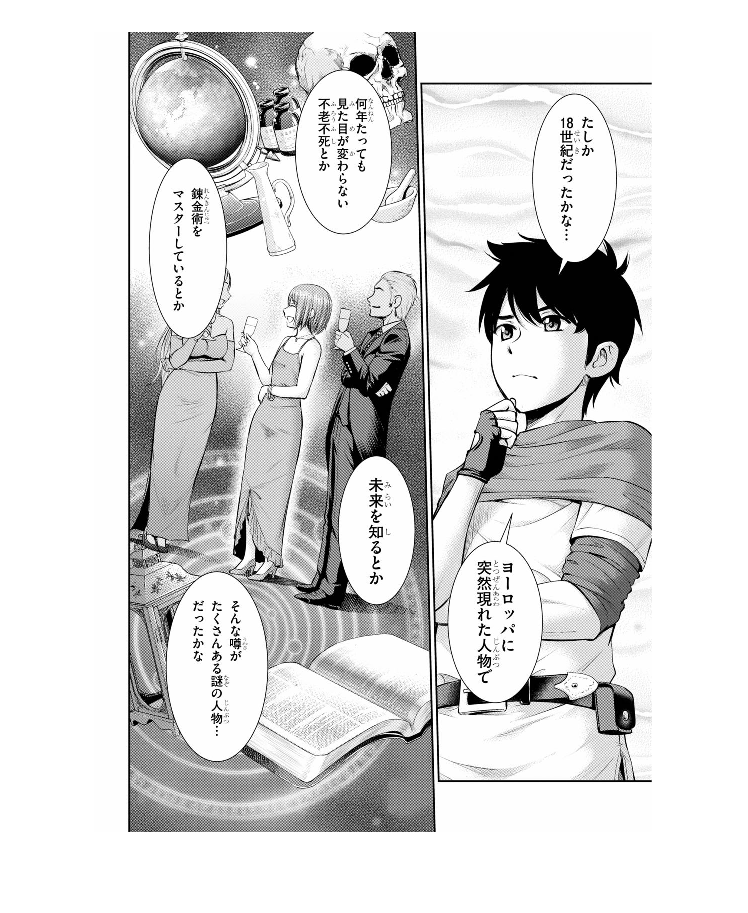

%if not(exist('I', 'var'))
    I = imread('image2.jpg');
   
    I = rgb2gray(I);
    imshow(I);

    %I = medfilt2(I,[3 1]);
    %imshow(I);

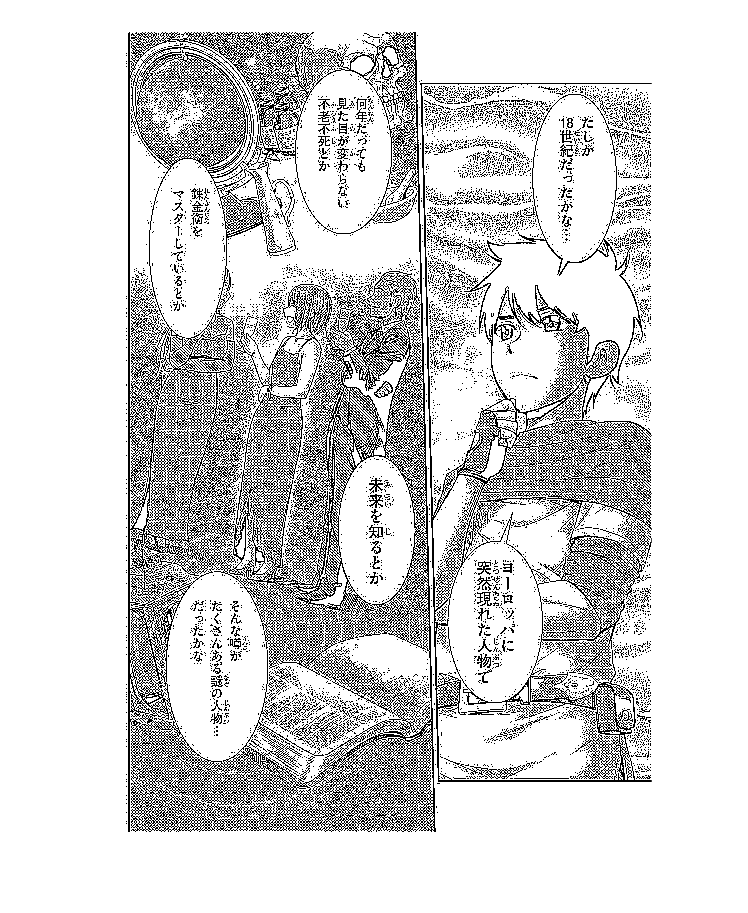

 
    M = colfilt(I, [5 5],'sliding', @mean);
    BW_Original = I > M - 3;  
%end

figure
imshow(BW_Original);

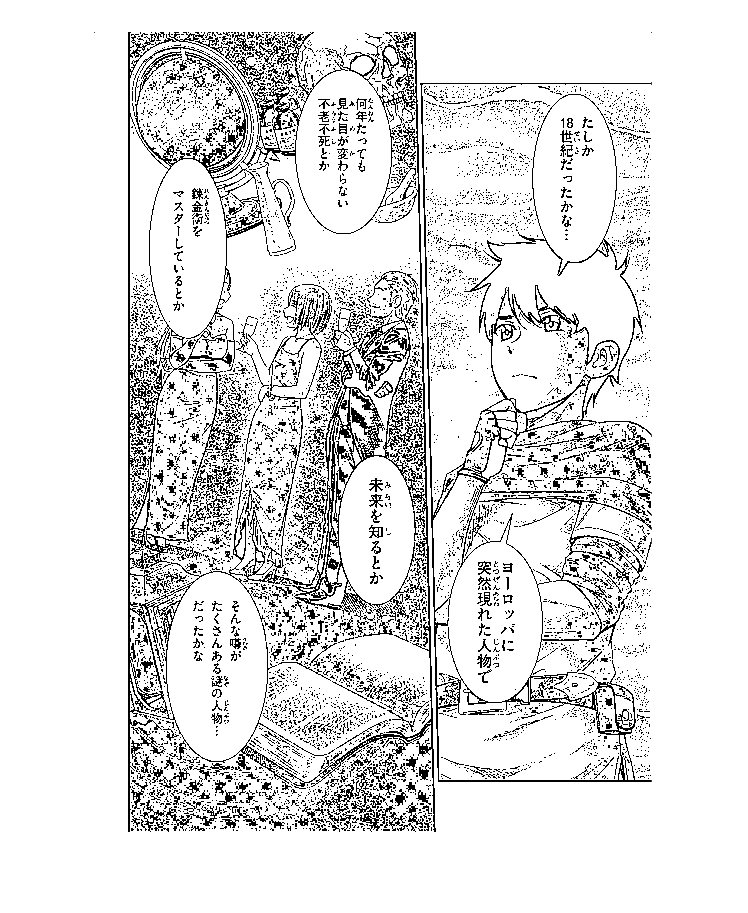

BW_Original=medfilt2(BW_Original);
imshow(BW_Original);

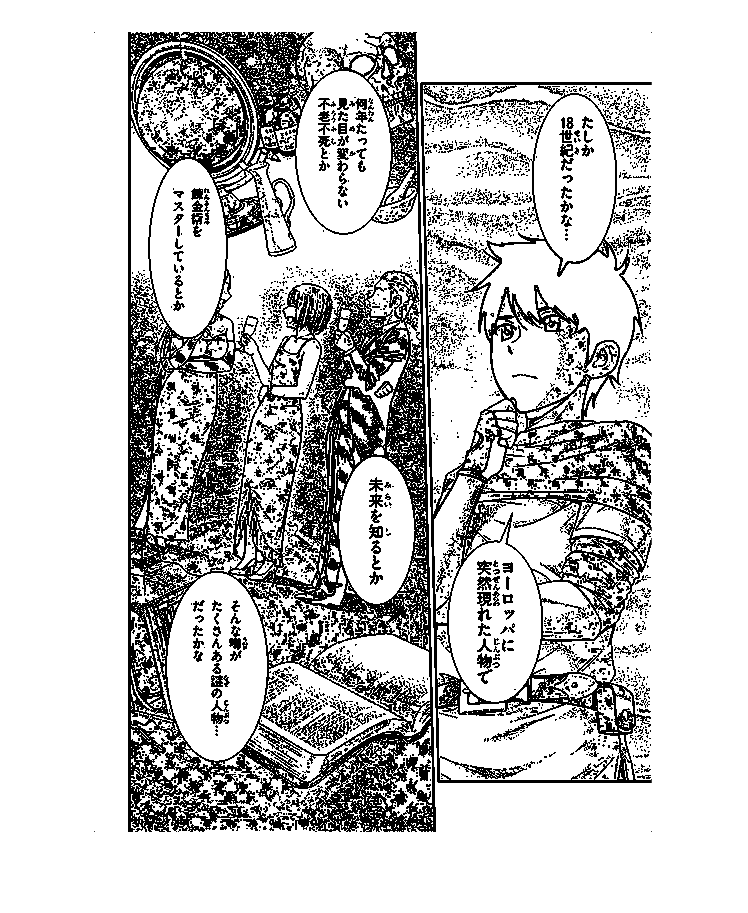

%BW_C = imclose(BW_Original, strel('disk', 3));
%BW_O = imopen(BW_C, strel('disk', 1));
BW_img = imerode(BW_Original, strel('disk', 1));

figure
imshow(BW_img);

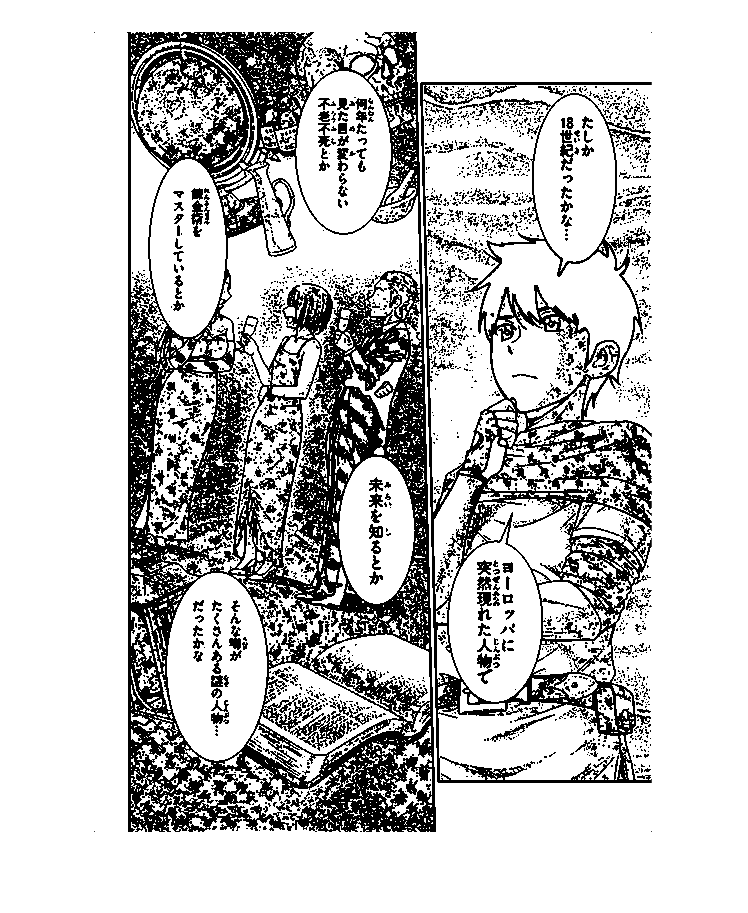

BW_img= medfilt2(BW_img,[3 3]);
imshow(BW_img);

CC = bwconncomp(BW_img);
stats = regionprops(CC, 'BoundingBox', "Circularity", "Extent", "Area","FilledArea","Image"); 
%stats = regionprops(CC, 'BoundingBox');

Matricula_detectada = 0;
BW_Result = BW_img;
numObjInRatio = 0;
numObjInRatioANDnumElements = 0;
for i=1:CC.NumObjects
    stat = stats(i);
    [x_ini, y_ini, height, width] = getBoundingBox(stat.BoundingBox);
    
    bubble_detectada = 0;
    relation = width/height;
    proportionOfWhite = stat.Area/stat.FilledArea;
    if relation >= 1/3 && relation <= 1.1 && proportionOfWhite > 0.7 && stat.Circularity > 0.6 && stat.Extent > 0.55
        Bubble = stat.Image;
        numObjInRatio = numObjInRatio + 1;
        CC2 = bwconncomp(not(Bubble));
        if CC2.NumObjects >= 4 && CC2.NumObjects <= 80 
            bubble_detectada = 1;
            numObjInRatioANDnumElements = numObjInRatioANDnumElements +1;  
            %stat.FilledArea
            %figure;
            %imshow(Bubble);
        end
    end
    
    if bubble_detectada == 0
        BW_Result(CC.PixelIdxList{i}) = 0;
    end
end
 
numObjInRatio

numObjInRatio = 1551

numObjInRatioANDnumElements

numObjInRatioANDnumElements = 130

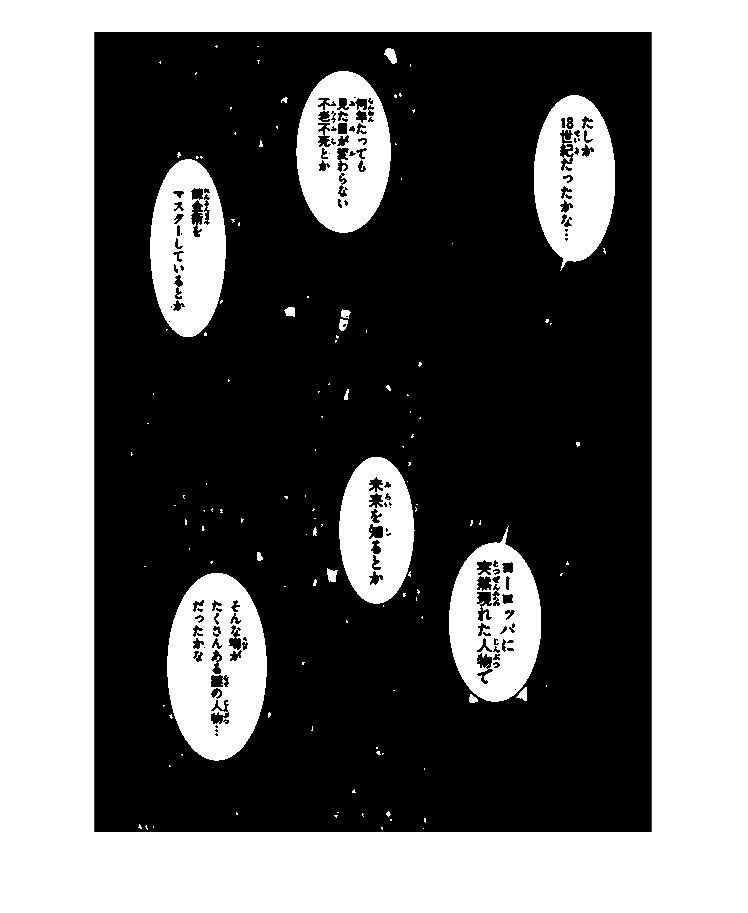


Matricula_detectada = BW_Result;
figure;
imshow(Matricula_detectada)

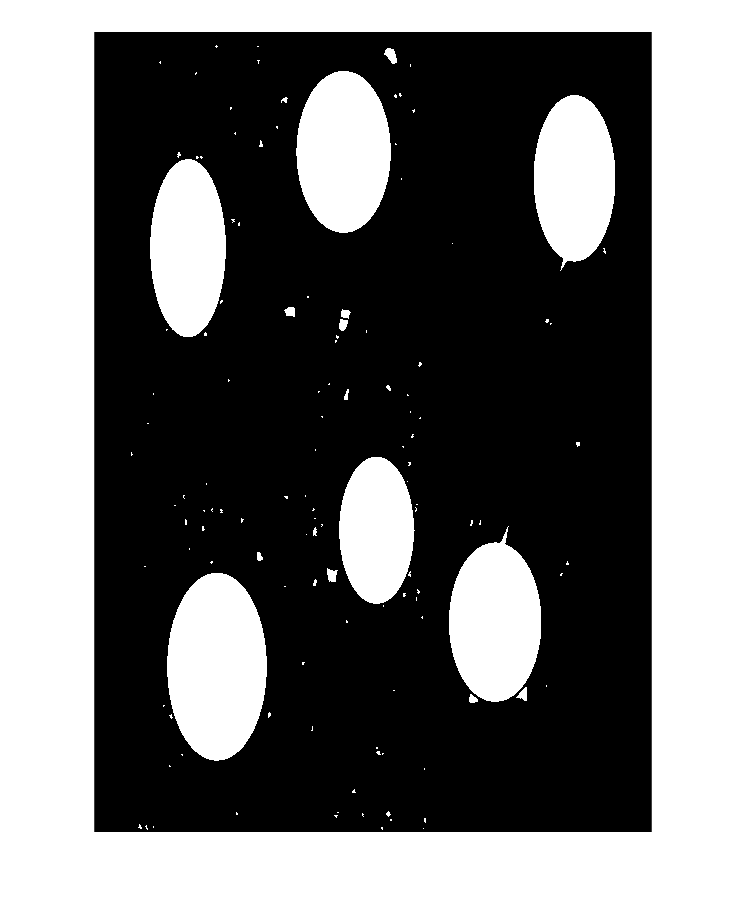

%CC3 = bwconncomp(Matricula_detectada);
Matricula_Def=imfill(Matricula_detectada, 'holes');
figure;
imshow(Matricula_Def);

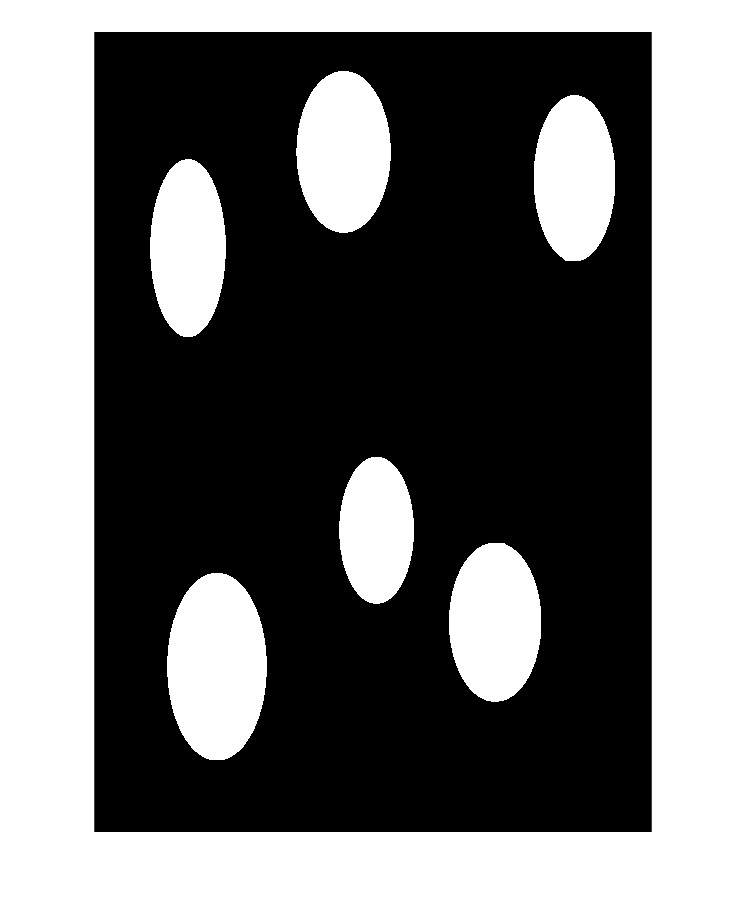

O = imopen(Matricula_Def, strel('disk', 15));
imshow(O);

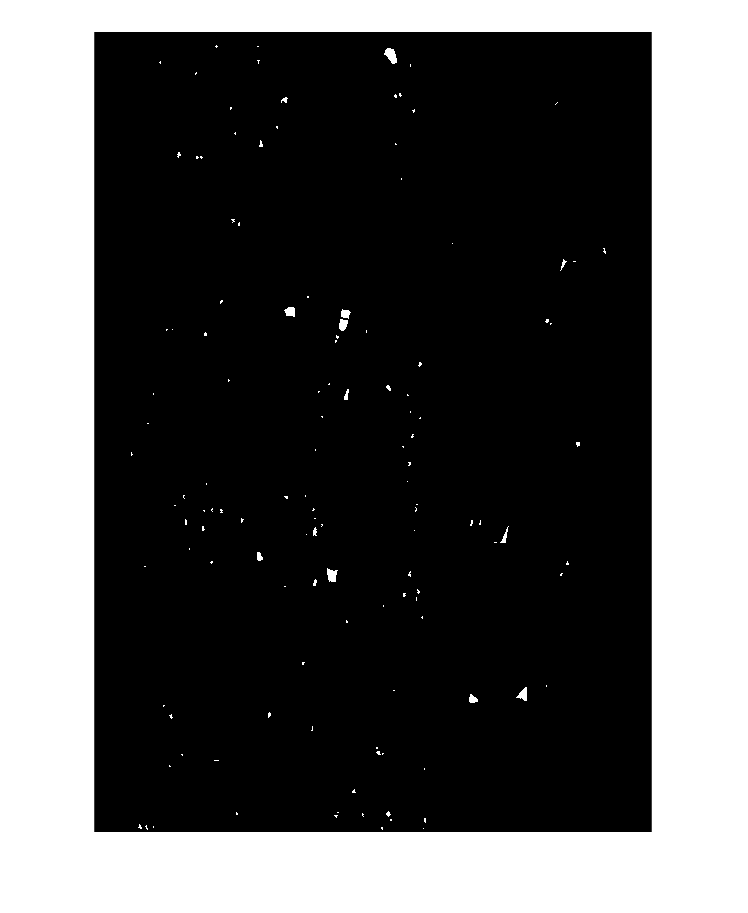

diff = abs(abs(O)-abs(Matricula_Def));
figure;
imshow(diff);